# Loading the data

%% How to threshold and save the thresholded brain image 
%
%    Load Data:
%        Load the PET image data and its header using spm_vol.
%
%    Set Threshold:
%        Choose a threshold value (e.g., 0.2) to consider BP values below it as unreliable.
%
%    Threshold the Image:
%        Create a new image variable (img_pet_thr).
%        Assign zero to voxels where BP is below the chosen threshold.
%
%    Save the Thresholded Image:
%        Specify an output directory.
%        Update the header's filename to save the thresholded image separately.
%        Use spm_write_vol to save the thresholded image as a NIfTI file.
%
%    Visualization:
%        Optionally, visualize the thresholded image using a tool like MRIcroGL.

% file processing 

currentDir = pwd;

dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

file = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';

inputDataPath = fullfile(dataFolder, file);

disp(inputDataPath);

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\..\..\..\..\data\health\pet\1_session_neuroimaging_basics\nii_data\wsrpet_nrm2018baseline1_bfsrtm_BP.nii


## Load the header of a PET image using spm_vol function (PATH).

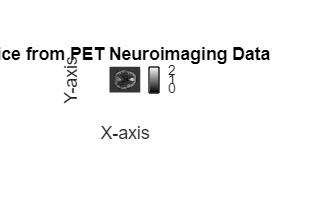

% spm_vol reads the header information of the neuroimaging file and 
% stores it in the variable V_pet.

% spm_read_vols reads the voxel intensity values from the neuroimaging file and 
% stores them in the variable img_pet.

V_pet = spm_vol(inputDataPath);
img_pet = spm_read_vols(V_pet);

% Choose a slice index (e.g., slice number 50)
slice_index = 50;

% Extract the slice from the 3D volume
slice_data = img_pet(:,:,slice_index);

% Plot the slice
imshow(slice_data, []);

title('Slice from PET Neuroimaging Data');
xlabel('X-axis');
ylabel('Y-axis');
colorbar; 

## Choose the threshold (BP values under 0.2 may be considered unreliable).

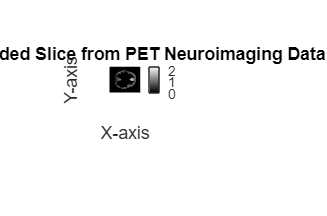

% Threshold the image (assign zero to all voxels where BP<thr).
% Here, BP values under 0.2 are considered unreliable

threshold_min = 0.2; 

img_pet_thr = img_pet; % Copy the PET image to new variable
img_pet_thr(img_pet_thr < threshold_min) = 0; % Assign zero to all voxels where BP<thr

% Extract the slice from the thresholded 3D volume
slice_data_thr = img_pet_thr(:,:,slice_index);

% Plot the slice
imshow(slice_data_thr, []);
title('Thresholded Slice from PET Neuroimaging Data');
xlabel('X-axis');
ylabel('Y-axis');
colorbar; % Display color bar for intensity scale

## Save the thresholded image using the V_pet header and spm_ write_vol function

% (IMPORTANT! Change the fname in the header. Otherwise you will overwrite the original image.).
% (IMPORTANT! Change the header filename. Otherwise you will overwrite the original image).
% Write the nifti-file

file_output = 'wsrpet_nrm2018baseline1_bfsrtm_BP_thresholded.nii'

file_output = 'wsrpet_nrm2018baseline1_bfsrtm_BP_thresholded.nii'

relativePath = ['/data/results/', file_output];

resultsPath = fullfile(pwd, relativePath);

V_pet.fname = resultsPath; 
spm_write_vol(V_pet,img_pet_thr); 

disp (resultsPath)

C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\data\results\wsrpet_nrm2018baseline1_bfsrtm_BP_thresholded.nii


## calling it as a function

clear;

currentDir = pwd;

dataFolder = fullfile(currentDir, '..', '..', '..', '..', 'data', 'health', 'pet', ...
    '1_session_neuroimaging_basics', 'nii_data');

file = 'wsrpet_nrm2018baseline1_bfsrtm_BP.nii';

threshold_min = 0.2; 

resultsPath = ['/data/results/'];

[V_pet, img_pet_thr] = thresholdBrainImage(dataFolder, file, threshold_min, resultsPath);

Thresholded image saved at: C:\Users\marku\OneDrive\Documents\MATLAB\healthcare\brain\main\data\results\wsrpet_nrm2018baseline1_bfsrtm_BP_thresholded.nii
